# **Convolutional Filters**

## Import image and acquire dimensions:

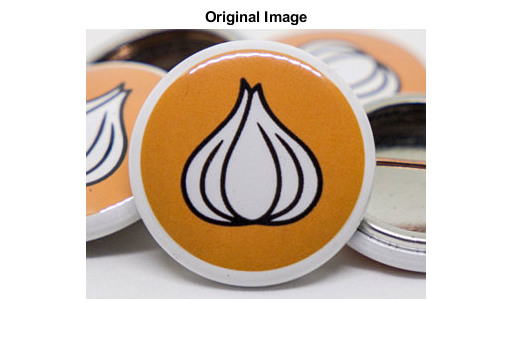

img = imread('garlicoin.jpg');
figure
imshow(img);
title("Original Image");

dimensions = size(img);
H = dimensions(1);
W = dimensions(2);
D = dimensions(3);

## Perform 3x3 Median Filtering:

- Pad image by 1 pixel to maintain the same size output image after convolution.

- For each color plane, loop through every pixel that is part of the original image

- Acquire all values of pixels under the filter centered at a particular [height, width]

- sort and take the median value of these acquired pixels, apply this value to the output image pixel.

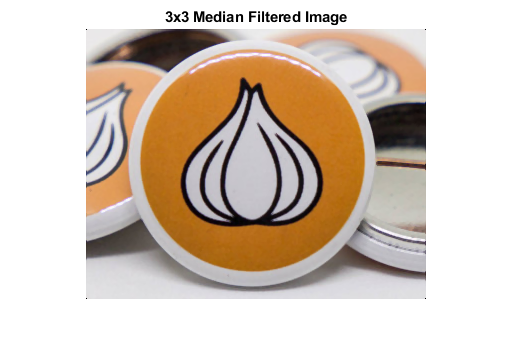

pad = 1;
filter = zeros(3,3);
WorkingImg = padarray(img, [pad,pad]);
FinalImg = zeros(size(img), 'uint8');

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            for i = -pad:pad
                for j = -pad:pad  
                    filter(i+pad+1, j+pad+1) = WorkingImg(height + i, width + j, rgb);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = uint8(median(sort(filter(:))));
        end
    end
end
figure
imshow(FinalImg);
title("3x3 Median Filtered Image");

Note that the colors in the image (especially the orange) seem more uniform and lighter from the median filtering.

## Perform 5x5 Median Filtering:

- Repeat process from 3x3 median filtering but instead using a 5x5 filter and a padding of 2.

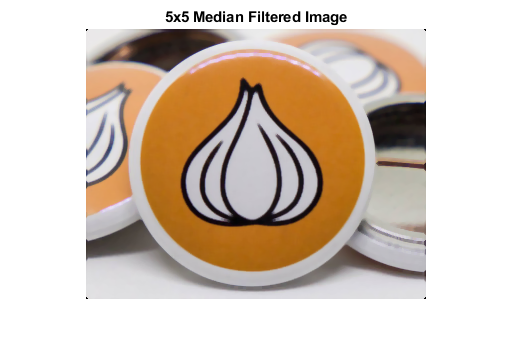

pad = 2;
filter = zeros(5,5);
WorkingImg = padarray(img, [pad,pad]);
FinalImg = zeros(size(img), 'uint8');

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            for i = -pad:pad
                for j = -pad:pad  
                    filter(i+pad+1, j+pad+1) = WorkingImg(height + i, width + j, rgb);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = uint8(median(sort(filter(:))));
        end
    end
end
figure
imshow(FinalImg);
title("5x5 Median Filtered Image");

Note that we can begin to see significant blurring around the edges of each color boundary, especially the black and white.

## Perform 15x15 Median Filtering:

- Repeat process from 3x3 median filtering but instead using a 15x15 filter and a padding of 7.

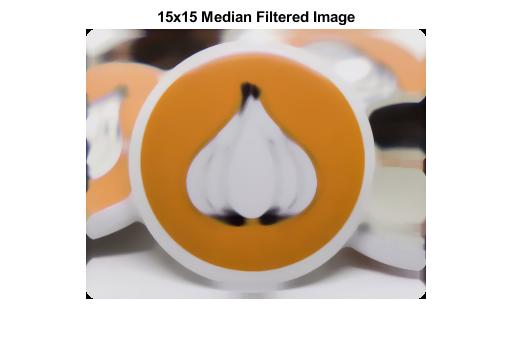

pad = 7;
filter = zeros(15,15);
WorkingImg = padarray(img, [pad,pad]);
FinalImg = zeros(size(img), 'uint8');

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            for i = -pad:pad
                for j = -pad:pad  
                    filter(i+pad+1, j+pad+1) = WorkingImg(height + i, width + j, rgb);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = uint8(median(sort(filter(:))));
        end
    end
end
figure
imshow(FinalImg);
title("15x15 Median Filtered Image");

Now we can most notably see the blurring that is occuring from taking the median value of a large surrounding area of each pixel.

## Perform 5x5 Min Filtering:

- Repeat process from 5x5 filtering but instead of sorting the values in the filter and taking the median, just simply take the minimum value present in the filter.

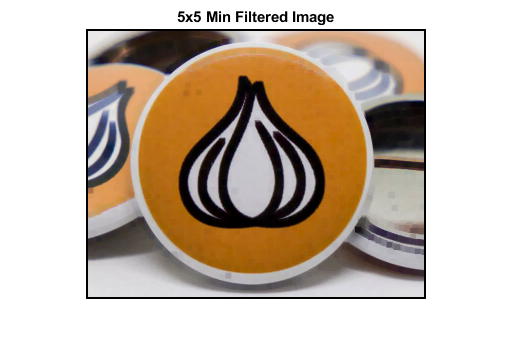

pad = 2;
filter = zeros(5,5);
WorkingImg = padarray(img, [pad,pad]);
FinalImg = zeros(size(img), 'uint8');

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            for i = -pad:pad
                for j = -pad:pad  
                    filter(i+pad+1, j+pad+1) = WorkingImg(height + i, width + j, rgb);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = uint8(min(filter(:)));
        end
    end
end
figure
imshow(FinalImg);
title("5x5 Min Filtered Image");

There are a few things to take note of here:

- Since we are taking the minimum value surrounding each pixel, we can expect that this image be, on average, darker than the original image.

- Near the boundaries we see a black border which comes from filtering regions that included part of the added padding, of which the assigned values of the pixels in the padding is 0, which therefore dominates the output of the min function.

- We also see areas of the image where small square regions of pixels all take the same color, this is due to the overlapping nature of the convolution. It so happened that there was a particularily dark pixel that dominated the min function for a group of filters that passed over it.

## Perform 5x5 Gaussian Filtering:

- This is similar to the previous 5x5 filtering techniques, but instead of performing a function to retrieve a single value from a region of pixels, we will use a Gaussian distribution to weight the value of each pixel in the region; which are then all summed together to assign to the output image pixel.

- The Bivariate Gaussian distribution will have the same sigma value in both dimensions and takes the value of 2.

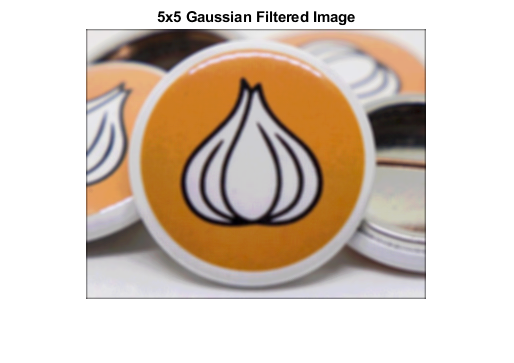

pad = 2;
filter = [
          0.0232 0.0338 0.0383 0.0338 0.0232;
          0.0338 0.0492 0.0558 0.0492 0.0338;
          0.0383 0.0558 0.0632 0.0558 0.0383;
          0.0338 0.0492 0.0558 0.0492 0.0338;
          0.0232 0.0338 0.0383 0.0338 0.0232
          ];
WorkingImg = padarray(img, [pad,pad]);
FinalImg = zeros(size(img), 'uint8');

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            sum = 0;
            for i = -pad:pad
                for j = -pad:pad  
                    sum = sum + WorkingImg(height + i, width + j, rgb) * filter(i+pad+1, j+pad+1);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = uint8(sum);
        end
    end
end
figure
imshow(FinalImg);
title("5x5 Gaussian Filtered Image");

This method produces the most smoothing given the size of the filter, as well as having the most uniform smoothing across the image.

## Perform 3x3 Sharpening Filtering:

- This is very similar to the Gaussian filtering in that each pixel under the filter is contributing in some way to the output image pixel.

- In this case however, we are trying to highlight a change in contrast continuity, hence the negative values surrounding the center pixel.

pad = 1;
filter = [
          -1, -1, -1;
          -1,  9, -1;
          -1, -1, -1
          ];
WorkingImg = double(padarray(img, [pad,pad]));
FinalImg = zeros(size(img));

for rgb = 1:D
    for height = 1+pad:H+pad
        for width = 1+pad:W+pad
            sum = 0;
            for i = -pad:pad
                for j = -pad:pad  
                    sum = sum + WorkingImg(height + i, width + j, rgb) * filter(i+pad+1, j+pad+1);
                end
            end
            FinalImg(height - pad, width - pad,rgb) = sum/9;
        end
    end
end
r = uint8(((255-0)/(max(FinalImg(:, :, 1))-min(FinalImg(:, :, 1))))*(FinalImg(:, :, 1)-min(FinalImg(:, :, 1))));

Error using  / 
Matrix dimensions must agree.

g = uint8(((255-0)/(max(FinalImg(:, :, 2))-min(FinalImg(:, :, 2))))*(FinalImg(:, :, 2)-min(FinalImg(:, :, 2))));
b = uint8(((255-0)/(max(FinalImg(:, :, 3))-min(FinalImg(:, :, 3))))*(FinalImg(:, :, 3)-min(FinalImg(:, :, 3))));

figure
imshow(FinalImg);
title("3x3 Sharpening Filtering")

Normally the sum would be divided by 9 before being assigned to the output image pixel, to be sure to equally weight each pixel under the current filter. However, I found that for the image in question, this resulted in the average pixel values being too low and giving a rather dark image. So I instead only divided the sum by 4.5 to brighten the image, and from the image we can easily see the prominant edges that have been brought out.